# Chapter 6, Section 6 (Part 3)

The goal of this activity is to do one more orthogonal diagonalization, this one requiring an additional Gram-Schmidt process to produce an orthgonal basis for one of the resulting eigenspaces.

# Example #1

Orthogonally diagonalize the matrix


$$A=\pmatrix{1 & 2 & 2\cr 2 & 1 & 2\cr 2 & 2 & 1}$$


**Solution: **We will use Matlab to check each of our steps, so we start by entering the matrix $A$.

A=[1 2 2;2 1 2;2 2 1]

A =      1     2     2
     2     1     2
     2     2     1


Looks good. Now we determine the characteristic polynomial.


$$\begin{array}{rcl}
|A-\lambda I|&=&\left|\matrix{1-\lambda & 2 & 2\cr 2 & 1-\lambda & 2\cr 2 & 2 & 1-\lambda}\right|\\
&=&(1-\lambda)\left|\matrix{1-\lambda & 2\cr 2 & 1-\lambda}\right|-2\left|\matrix{2 & 2\cr 2 & 1-\lambda}\right|+2\left|\matrix{2 & 1-\lambda\cr 2 & 2}\right|\\
&=&(1-\lambda)(1-2\lambda+\lambda^2-4)-2(2-2\lambda-4)+2(4-2+2\lambda)\\
&=&(1-\lambda)(\lambda^2-2\lambda-3)-2(-2\lambda-2)+2(2+2\lambda)\\
&=&\lambda^2-2\lambda-3-\lambda^3+2\lambda^2+3\lambda+4\lambda+4+4+4\lambda\\
&=&-\lambda^3+3\lambda^2+9\lambda+5
\end{array}$$


Let's check this with Matlab.

syms lambda
p=charpoly(A,lambda)

$$p = \lambda^{3}-3\,\lambda^{2}-9\,\lambda -5$$

We'll see that this is acceptable when we set our characteristic polynomial equal to zero, our first step will be to multiply both sides by -1.


$$\begin{array}{rcl}
0&=&-\lambda^3+3\lambda^2+9\lambda+5\\
0&=&\lambda^3-3\lambda^2-9\lambda-5
\end{array}$$


Same as what Matlab returned. Using the Rational Root theorem, to find a rational root of the form $p/q$, the $p$ must divide the constant term $-5$, and the $q$ must divide the leading coefficient 1. Therefore, the possibilities are:


$$\begin{array}{rcl}
p&=&\pm 1\\
q&=&\pm 1, \pm 5\\
\frac{p}{q}&=&\pm 1, \pm 5
\end{array}$$


Using our shortcut (called **synthetic division**), we can write:

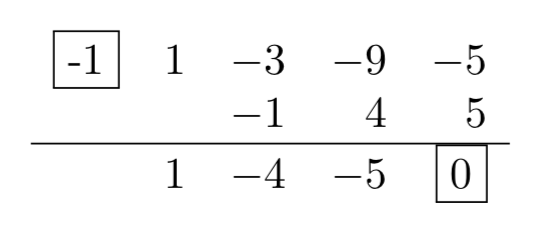

Because $-1$ is a root, $\lambda+1$ is a factor and:


$$\begin{array}{rcl}
(\lambda+1)(\lambda^2-4\lambda-5)&=&0\\
(\lambda+1)(\lambda-5)(\lambda+1)&=&0\\
(\lambda+1)^2(\lambda-5)&=&0
\end{array}$$


And we can check this factoring with Matlab.

factor(p,lambda)

$$ans = \left(\begin{array}{ccc} \lambda -5 & \lambda +1 & \lambda +1 \end{array}\right)$$

Therefore, $\lambda_1=5$ is an eigenvalue of algebraic multiplicity 1 and $\lambda_2=-1$ is an eigenvalue of algebraic multiplicity 2. We can check this with Matlab.

solve(p==0,lambda)

$$ans = \left(\begin{array}{c} -1\\ -1\\ 5 \end{array}\right)$$

Same answer. Now, let's find a basis for the eigenspace $E_{\lambda_1}$.

Since $\qquad A=\pmatrix{1 & 2 & 2\cr 2 & 1 & 2\cr 2 & 2 & 2}\qquad\text{then}\qquad A-5I=\pmatrix{-4 & 2 & 2\cr 2 & -4 & 2\cr 2 & 2 & -4}$

Note that we simply subtracted 5 from each diagonal element. Now we will row reduce.


$$\pmatrix{-4 & 2 & 2\cr 2 & -4 & 2\cr 2 & 2 & -4}\ \matrix{R_1\leftrightarrow R_3\cr ~\cr ~}\qquad\longrightarrow\qquad\pmatrix{2 & 2 & -4\cr 2 & -4 & 2\cr -4 & 2 & 2}\ \matrix{(1/2)R_1\cr ~\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & -2\cr 2 & -4 & 2\cr -4 & 2 & 2}$$


Next,


$$\pmatrix{1 & 1 & -2\cr 2 & -4 & 2\cr -4 & 2 & 2}\ \matrix{~\cr R_2-2R_1\cr R_3+4R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & -2\cr 0 & -6 & 6\cr 0 & 6 & -6}\ \matrix{~\cr (-1/6)R_2\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & -2\cr 0 & 1 & -1\cr 0 & 6 & -6}$$


Finally,


$$\pmatrix{1 & 1 & -2\cr 0 & 1 & -1\cr 0 & 6 & -6}\ \matrix{R_1-R_2\cr ~\cr R_3-6R_2}\qquad\longrightarrow\qquad\pmatrix{1 & 0 & -1\cr 0 & 1 & -1\cr 0 & 0 & 0}$$


We can check this with Matlab.

rref(A-5*eye(3))

ans =      1     0    -1
     0     1    -1
     0     0     0


Same answer. Now, notice we have two pivot columns and one free column.


$$\pmatrix{[1] & 0 & -1\cr 0 & [1] & -1\cr 0 & 0 & 0}$$


Note that 1 times the first column, plus 1 times the second column, plus 1 times the third column gives us the zero vector, so the basis for eigenspace of $\lambda_1=5$ is:


$$E_{\lambda_1}=\left\{\pmatrix{1\cr 1\cr 1}\right\}$$


Therefore, the geometric multiplicity of $\lambda_1=5$ (the dimension of $E_{\lambda_1}$) is 1. Now, let's get the basis for the eigenspace $E_{\lambda_2}$.

Since $\qquad A=\pmatrix{1 & 2 & 2\cr 2 & 1 & 2\cr 2 & 2 & 2}\qquad\text{then}\qquad A-(-1)I=\pmatrix{2 & 2 & 2\cr 2 & 2 & 2\cr 2 & 2 & 2}$

Note that we simply subtracted $-1$ from each diagonal element. Now, we row reduce. 


$$\pmatrix{2 & 2 & 2\cr 2 & 2 & 2\cr 2 & 2 & 2}\ \matrix{(1/2)R_1\cr ~\cr ~}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 1\cr 2 & 2 & 2\cr 2 & 2 & 2}\ \matrix{~\cr R_2-2R_1\cr R_3-2R_1}\qquad\longrightarrow\qquad\pmatrix{1 & 1 & 1\cr 0 & 0 & 0\cr 0 & 0 & 0}$$


We can check this with Matlab.

rref(A-(-1)*eye(3))

ans =      1     1     1
     0     0     0
     0     0     0


Same answer. Now, notice we have one pivot column and two free columns.


$$\pmatrix{[1] & 1 & 1\cr 0 & 0 & 0\cr 0 & 0 & 0}$$


Note that $-1$ times the first column, plus 1 times the second column, plus 0 times the third column gives us the zero vectors. Hence, $(-1,1,0)^T$ is an eigenvector. Second, notice that $-1$ times the first column, plus 0 times the second column, plus 1 times the third column gives us the zero vector. Hence, $(-1,0,1)^T$ is an eigenvector. Therefore, a basis for the eigenspace of $\lambda_2=-1$ is:


$$E_{\lambda_2}=\left\{\pmatrix{-1\cr 1\cr 0},\ \pmatrix{-1\cr 0\cr 1}\right\}$$


 Therefore, the geometric multiplicity of $\lambda_2=-1$ (the dimension of $E_{\lambda_2}$) is 2. 

We' ve seen in previous activities that the algebraic multiplicity is always greater than or equal to the geometric multiplicity. We've seen many cases where the algebraic multiplicity of an eigenvalue might be 2, but there was only one eigenvector associated with the eigenvalue, so the algebraic multiplicity was greater than the geometric multiplicity. But now, with symmetric matrices, we are seeing something different.

**Important Fact: **If A is an $n\times n$ real symmetric matrix, the dimension of the eigenspace (geometric multiplicity) for each eigenvalue $\lambda$ equals the multiplicity (algebraic multiplicity) of $\lambda$ as a root of the characteristic equation.

Now, we can check our eigenvalues and eigenvectors with Matlab's eig command.

[V,D]=eig(sym(A))

$$V = \left(\begin{array}{ccc} 1 & -1 & -1\\ 1 & 1 & 0\\ 1 & 0 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{ccc} 5 & 0 & 0\\ 0 & -1 & 0\\ 0 & 0 & -1 \end{array}\right)$$

Precisely the same. Now, we have two distinct eigenvalues. So, the eigenvectors in  $E_{\lambda_1}$ should be orthogonal to the eigenvectors in $E_{\lambda_2}$. Note that


$$\pmatrix{1\cr 1\cr 1}\cdot\pmatrix{-1\cr 1\cr 0}=(1)(-1)+(1)(1)+(1)(0)=0$$


and:


$$\pmatrix{1\cr 1\cr 1}\cdot\pmatrix{-1\cr 0\cr 1}=(1)(-1)+(1)(0)+(1)(1)=0$$


And we can check this with Matlab. Let's store the columns of the matrix V in v1, v2, and v3.

v1=V(:,1);
v2=V(:,2);
v3=V(:,3);

Note that $\mathbf v_1\in E_{\lambda_1}$ and $\mathbf v_2, \mathbf v_3\in E_{\lambda_2}$, so

dot(v1,v2)

$$ans = 0$$

dot(v1,v3)

$$ans = 0$$

agree with our hand-calculations above. However, note what happens when we take the dot product of the two eigenvectors in $E_{\lambda_2}$.


$$\pmatrix{-1\cr 1\cr 0}\cdot\pmatrix{-1\cr 0\cr 1}=(-1)(-1)+(1)(0)+(0)(1)=1$$


We can check this with Matlab.

dot(v2,v3)

$$ans = 1$$

Same answer. The dot product is not zero, so $\mathbf v_2$ and $\mathbf v_3$ are not orthogonal. Now, in order to orthogonally diagonalize the matrix $A$, we need an orthogonal basis for $E_{\lambda_2}$. We will use the Gram-Schmidt process to produce an orthogonal basis for 


$$E_{\lambda_2}=\{\textbf v_2,\ \textbf v_3\}=\left\{\pmatrix{-1\cr 1\cr 0},\ \pmatrix{-1\cr 0\cr 1}\right\}$$


Now, for the Gram-Schmidt process, we first let $\textbf w_2=\textbf v_2=(-1,1,0)^T$. 

w2=v2

$$w2 = \left(\begin{array}{c} -1\\ 1\\ 0 \end{array}\right)$$

Then we calculate the orthogonal projection of $\textbf v_3$ onto $\textbf w_2$ and subtract the result from $\textbf v_3$, which gives us the orthogonal component.


$$\begin{array}{rcl}
\textbf w_3&=&\textbf v_3-\frac{\textbf v_3\cdot\textbf w_2}{\textbf w_2\cdot\textbf w_2}\textbf w_2\\
\textbf w_3&=&\pmatrix{-1\cr 0\cr 1}-\frac{(-1,0,1)\cdot(-1,1,0)}{(-1,1,0)\cdot(-1,1,0)}\pmatrix{-1\cr 1\cr 0}\\
\textbf w_3&=&\pmatrix{-1\cr 0\cr 1}-\frac12\pmatrix{-1\cr 1\cr 0}\\
\textbf w_3&=&\pmatrix{-1\cr 0\cr 1}+\pmatrix{1/2\cr -1/2\cr 0}\\
\textbf w_3&=&\pmatrix{-1/2\cr -1/2\cr 1}
\end{array}$$


Now we can check these steps with Matlab.

w3=v3-dot(v3,w2)/dot(w2,w2)*w2

$$w3 = \left(\begin{array}{c} -\frac{1}{2}\\ -\frac{1}{2}\\ 1 \end{array}\right)$$

Of course, we can also check this with Matlab's **orth** command. We want an orthogonal basis for the second and third columns of matrix V.

orth(V(:,[2,3]),'skipnormalization')

$$ans = \left(\begin{array}{cc} -1 & -\frac{1}{2}\\ 1 & -\frac{1}{2}\\ 0 & 1 \end{array}\right)$$

Same as our hand-calculations. Now, we know that any scalar multiple of an eigenvector is also an eigenvector, so we will multiply the second vector by 2 and use the result in the basis for the eigenspace of $\lambda_2=-1$.


$$E_{\lambda_2}=\left\{\pmatrix{-1\cr 1\cr 0},\ \pmatrix{-1\cr -1\cr 2}\right\}$$


And:


$$E_{\lambda_1}=\left\{\pmatrix{1\cr 1\cr 1}\right\}$$


Now, to make our following steps clear to our readers, let's update $\textbf w_1$, $\textbf w_2$, and $\textbf w_3$ to be the vectors in these two eigenspaces. That is,


$$E_{\lambda_1}=\{\textbf w_1\}=\left\{\pmatrix{1\cr 1\cr 1}\right\}\qquad\text{and}\qquad E_{\lambda_2}=\left\{\textbf w_2,\ \textbf w_3\right\}=\left\{\pmatrix{-1\cr 1\cr 0},\ \pmatrix{-1\cr -1\cr 2}\right\}$$


w1=[1;1;1];
w2=[-1;1;0];
w3=[-1;-1;2];

Recall that $\lambda_1=5$ and $\lambda_2=-1$ are distinct eigenvalues, so $\mathbf w_1$ should be orthogonal to both $\textbf w_2$ and $\textbf w_3$. It is very easy to check this by hand, but let's check this with Matlab.

dot(w1,w2)

ans = 0

dot(w1,w3)

ans = 0

Both zero, so orthogonal. Now, the difference between these two bases and our previous bases for the eigenspaces of $\lambda_1$ an d $\lambda_2$, is this time the two vectors in $E_{\lambda_2}$ are now orthogonal.

dot(w2,w3)

ans = 0

Zero! So they are orthogonal. Now, in our last activity (Chapter 6, Section 6 (Part 2)), we showed that the columns of a matrix are mutually orthogonal if and only if


$$W^TW=\pmatrix{\textbf w_1^T\cr \textbf w_2^T\cr \textbf w_3^T}\pmatrix{\textbf w_1 & \textbf w_2 & \textbf w_3}=\pmatrix{||\textbf w_1||^2 & \textbf w_1^T\textbf w_2 & \textbf w_1^T\textbf w_3\cr \textbf w_2^T\textbf w_1 & ||\textbf w_2||^2 & \textbf w_2^T\textbf w_3\cr \textbf w_3^T\textbf w_1 & \textbf w_3^T\textbf w_2 & ||\textbf w_3||^2}=\pmatrix{||\textbf w_1||^2 & 0 & 0\cr 0 & ||\textbf w_2||^2 & 0\cr 0 & 0 & ||\textbf w_3||^2}$$


If all the components that do not lie on the main diagonal are zero, then the vectors are orthogonal. The components on the diagonal are the squares of the lengths of each column vector. Let's create a matrix $W$ with our $\textbf w_1$, $\textbf w_2$, and $\textbf w_3$ as the columns.

W=[w1,w2,w3]

W =      1    -1    -1
     1     1    -1
     1     0     2


Now, let's calculate $W^TW$.

W.'*W

ans =      3     0     0
     0     2     0
     0     0     6


Because every element off the main diagonal is zero, our column vectors are mutually orthogonal. Secondly, the square of the length of the vector $\textbf w1$ is 3, of $\textbf w_2$ is 2, and of $\textbf w_3$ is 6. We can also check this with Matlab's norm command.

norm(w1)^2

ans = 3.0000

norm(w2)^2

ans = 2.0000

norm(w3)^2

ans = 6.0000

Same answers. Now, this means that $||\textbf w_1||^2=3$, $||\textbf w_2||^2=2$, and $||\textbf w_3||^2=6$. This means that $||\textbf w_1||=\sqrt3$, $||\textbf w_2||=\sqrt2$, and $||\textbf w_3||=\sqrt6$. Now, if we divide each column of our matrix $W$ by its length, we will have an orthognal matrix.


$$W=\pmatrix{1 & -1 & -1 \cr 1 & 1 & -1\cr 1 & 0 & 2}\qquad\longrightarrow\qquad Q=\pmatrix{1/\sqrt3 & -1/\sqrt2 & -1/\sqrt6\cr 1/\sqrt3 & 1/\sqrt 2 & -1/\sqrt 6\cr 1/\sqrt 3 & 0 & 2/\sqrt 6}$$


Some might prefer to simplify this by eliminating the radicals in the denominators. If we multiply the numerator and denominator of the entries in the first column by $\sqrt3$, the entries in the second column by $\sqrt2$, and the entries in the third column by $\sqrt6$,  we get:


$$Q=\pmatrix{\sqrt3/3 & -\sqrt2/2 & -\sqrt6/6\cr \sqrt3/3 & \sqrt2/2 &-\sqrt6/6\cr \sqrt3/3 & 0 & \sqrt6/3}$$


And we can check this with Matlab. 

Q=sym([w1/norm(w1),w2/norm(w),w3/norm(w3)]);
Q=simplify(Q)

$$Q = \left(\begin{array}{ccc} \frac{\sqrt{3}}{3} & -\frac{\sqrt{2}}{2} & -\frac{\sqrt{6}}{6}\\ \frac{\sqrt{3}}{3} & \frac{\sqrt{2}}{2} & -\frac{\sqrt{6}}{6}\\ \frac{\sqrt{3}}{3} & 0 & \frac{\sqrt{6}}{3} \end{array}\right)$$

This time our orthogonal vectors have length one. That is, they are orthonormal, so this time $Q^TQ$ should equal $I$. Let's check this with Matlab.

Q.'*Q

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

Perfect! Now, to create our diagonal matrix $D$, we must put the corresponding eigenvalues in the same order on the main diagonal.


$$D=\pmatrix{5 & 0 & 0\cr 0 & -1 & 0\cr 0 & 0 & -1}$$


Thus, our orthogonal diagonalization is $Q^TAQ=D$; that is,


$$\pmatrix{\sqrt3/3 & -\sqrt2/2 & -\sqrt6/6\cr \sqrt3/3 & \sqrt2/2 &-\sqrt6/6\cr \sqrt3/3 & 0 & \sqrt6/3}^T\pmatrix{1 & 2 & 2\cr 2 & 1 & 2\cr 2 & 2 & 1}\pmatrix{\sqrt3/3 & -\sqrt2/2 & -\sqrt6/6\cr \sqrt3/3 & \sqrt2/2 &-\sqrt6/6\cr \sqrt3/3 & 0 & \sqrt6/3}=\pmatrix{5 & 0 & 0\cr 0 & -1 & 0\cr 0 & 0 & -1}$$


Let's check this with Matlab.

Q.'*A*Q

$$ans = \left(\begin{array}{ccc} 5 & 0 & 0\\ 0 & -1 & 0\\ 0 & 0 & -1 \end{array}\right)$$

Bingo! We're done.

# A Faster Way with Matlab

Let's enter our matrix 


$$A=\pmatrix{1 & 2 & 2\cr 2 & 1 & 2\cr 2 & 2 & 1}$$


 again.

A=[1 2 2;2 1 2;2 2 1]

A =      1     2     2
     2     1     2
     2     2     1


Now, let's find the eigenvalues and eigenvectors.

[V,D]=eig(sym(A))

$$V = \left(\begin{array}{ccc} 1 & -1 & -1\\ 1 & 1 & 0\\ 1 & 0 & 1 \end{array}\right)$$

$$D = \left(\begin{array}{ccc} 5 & 0 & 0\\ 0 & -1 & 0\\ 0 & 0 & -1 \end{array}\right)$$

There is our same diagonal matrix. Not, let's create our orthogonal matrix $Q$.

Q=orth(V);
Q=simplify(Q)

$$Q = \left(\begin{array}{ccc} \frac{\sqrt{3}}{3} & -\frac{\sqrt{2}}{2} & -\frac{\sqrt{6}}{6}\\ \frac{\sqrt{3}}{3} & \frac{\sqrt{2}}{2} & -\frac{\sqrt{6}}{6}\\ \frac{\sqrt{3}}{3} & 0 & \frac{\sqrt{6}}{3} \end{array}\right)$$

And check.

Q.'*A*Q

$$ans = \left(\begin{array}{ccc} 5 & 0 & 0\\ 0 & -1 & 0\\ 0 & 0 & -1 \end{array}\right)$$

That equals or diagonal matrix $D$, so we've shown that $A^TAQ=D$. Wow! Quick. :-)